# Spectacle magnification

Spectacle and contact lenses produce magnificantion and minification of the visual world, with the size of this effect dependent upon the refractive power of the lens. In this application, we show how to calculate the angular magnification (as seen by the retina) that is produced by an artificial lens, and then examine how this effect varies with the optical power of the lens.

## Basic calculation

The magnification produced by a lens is calculated for a particular eye under study. We first define a model eye structure that has –5 diopters of spherical ametropia. This is an eye that is myopic (near-sighted).

modelEye = modelEyeParameters('sphericalAmetropia',-5);

We can then obtain the degree of angular magnification produced in this eye produced by the appropriate spectacle corrective lens:

calcAngularMagnification(modelEye,'spectacleLens',-5)

ans = 0.9264

The resulting value indicates the scaling of the visual world as seen by the eye through the lens. As the value is less than one, this indicates that the visual world is "minified", or reduced in apparent size. The visual world is reduced in size by about 7.5% when wearing a –5 diopter spectacle lens.

Contact lenses produce magnification as well, but the effect is smaller, as the lens is located closer to the optical center of the eye:

calcAngularMagnification(modelEye,'contactLens',-5)

ans = 0.9864

Now, for the same optical correction, the "minification" is only 1.5% or so.

## Behind the calculation

To determine the magnification produced by a corrective lens, the function `calcAngularMagnification` performs ray tracing to identify the angle at which a ray, leaving a point in the visual world, intersects the center of the aperture stop of the eye. This angle is calculated with and without the lens present, and the ratio of the angles provides the degree of angular magnification.

## Validation

In 1963, Gerlad Westheimer used a model eye to calculate the degree of angular magnification that would be produced by spectacles and contact lenses of various optical strengths:

- G Westheimer. "The visual world of the new contact lens wearer." The Australian Journal of Optometry 46.5 (1963): 124-127

We can replicate Westheimer's calculation, and compare our result to his. First, we create a model eye that is similar to what Westheimer used. He assumed a spherical cornea, with 43.5 diopters of keratometric power:

kvals= [43.5, 43.5, 0, 0, 0];
modelEye = modelEyeParameters('kvals',kvals);

Next, we loop over lenses of varying spherical refractive, ranging from -11 to +7 diopters. For each lens, we obtain and store the magnification that would be produced by a contact or spectacle lens:

d = -11:1:7;
for ii = 1:length(d)
    Mspectacle(ii) = ...
        calcAngularMagnification(modelEye,'spectacleLens',d(ii));
    Mcontact(ii) = ...
        calcAngularMagnification(modelEye,'contactLens',d(ii));
end

We convert the values to the % increase or decrease in magnification, and observe that the functions agree well with Westheimer's calculations:

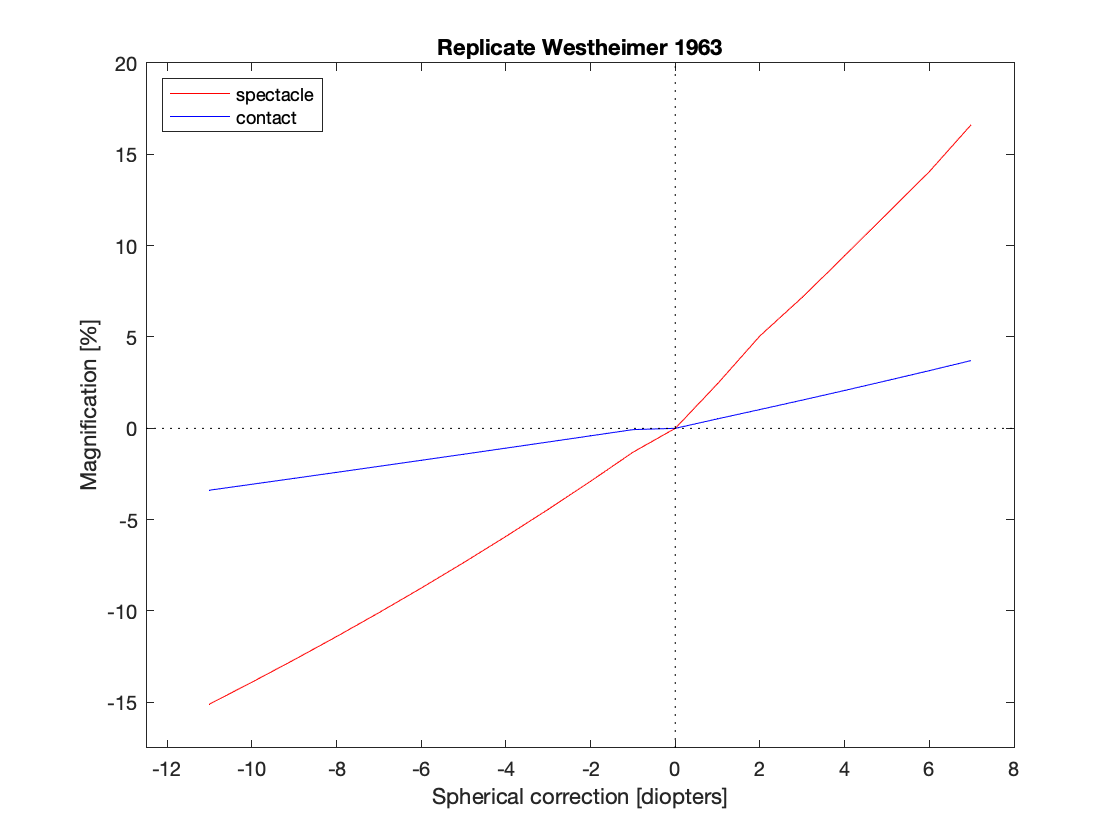

pHandle(1)=plot(d,100*(Mspectacle-1),'-r');
hold on
pHandle(2)=plot(d,100*(Mcontact-1),'-b');
xlim([-12.5 8]);
ylim([-17.5 20]);
plot([0 0],[-17.5 20],':k')
plot([-12.5 8],[0 0],':k')
ylabel('Magnification [%]');
xlabel('Spherical correction [diopters]');
legend( pHandle,{'spectacle','contact'},'Location','northwest');
title('Replicate Westheimer 1963');